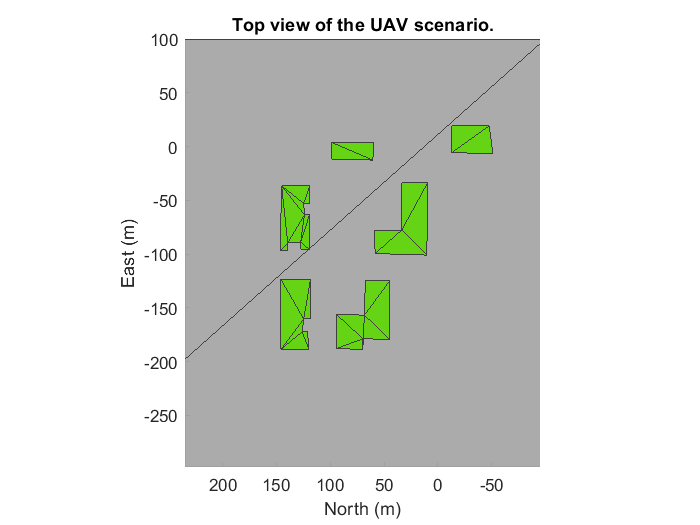

% first a UAV scenario is created.
scene = uavScenario("UpdateRate",2,"ReferenceLocation",[75 -46 0]);


color.Gray = 0.651*ones(1,3);
color.Green = [0.3922 0.8314 0.0745];
color.Red = [1 0 0];

% a gray coloured ground is added.
addMesh(scene,"polygon",{[-300 -100; 100 -100; 100 350; -300 350],[-4 0]},color.Gray)



% buildingData.mat is used to get coordinates for the vertices of building.
load("buildingData.mat");


addMesh(scene,"polygon",{buildingData{3}(2:10,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{4}(2:9,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{5}(1:end-1,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{7}(1:end-1,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{9}(1:end-1,:),[0 15]},color.Green)
addMesh(scene,"polygon",{buildingData{10}(1:end-1,:),[0 30]},color.Green)


show3D(scene);
xlim([-298 100])
ylim([-95 235])
zlim([-0.0 50.0])
title('Top view of the UAV scenario.')

%view angle for top view.
view([-90.0 90.0])

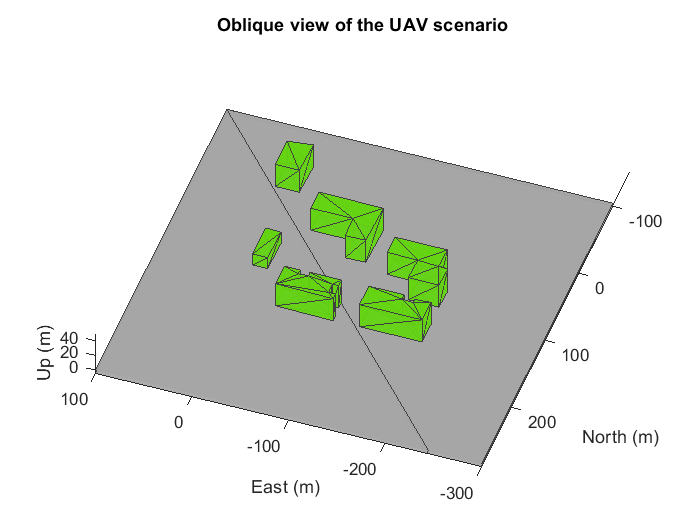



show3D(scene);
xlim([-300 100])
ylim([-150 289])
zlim([-4.0 50.0])
title('Oblique view of the UAV scenario')

%view angle for oblique view.
view([199.3 44.0])

%flightData.mat is used to get position and orientation for uav path

load("flightData.mat")

% platform is created.
plat = uavPlatform("UAV",scene,"ReferenceFrame","NED", ...
    "InitialPosition",position(:,:,1),"InitialOrientation",eul2quat(orientation(:,:,1)));

% quadrotor is added.
updateMesh(plat,"quadrotor",{40},color.Red,[0 0 0],eul2quat([0 0 pi]))

%lidar point cloud generator is mounted on the uav

lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.3324099,...
    "ElevationLimits",[-20 20],"ElevationResolution",1.25,...
    "MaxRange",100,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0,0,-1]);

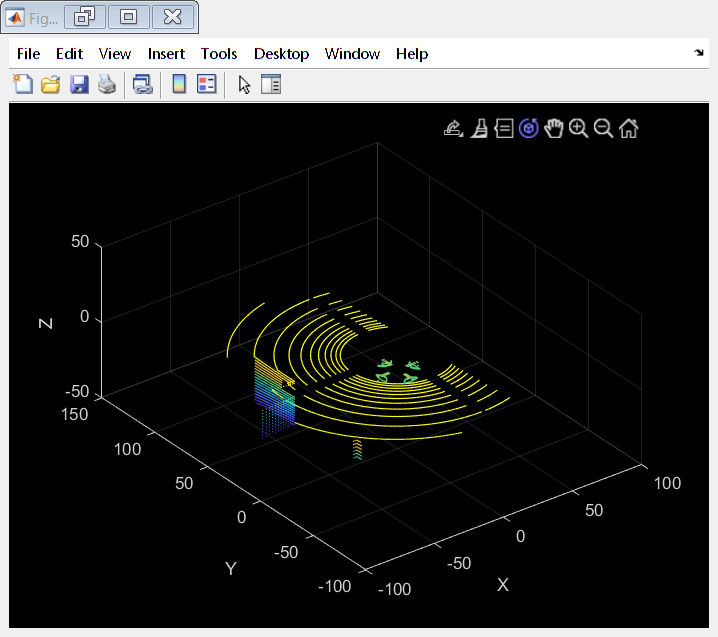

[ax,plotFrames] = show3D(scene);
xlim([-250 100])
ylim([-100 180])
zlim([0 50])
view([0,90])
axis equal
hold on

%line plot for the trajectory.
traj = plot3(nan,nan,nan,"Color",[1 1 1],"LineWidth",2);
traj.XDataSource = "position(:,1,1:idx+1)";
traj.YDataSource = "position(:,2,1:idx+1)";
traj.ZDataSource = "position(:,3,1:idx+1)";

%scatter plot for the  point cloud.
colormap("hsv")
pt = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
    "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(pt.Location(:,:,1),[],1)";
scatterplot.YDataSource = "reshape(pt.Location(:,:,2),[],1)";
scatterplot.ZDataSource = "reshape(pt.Location(:,:,3),[],1)";
scatterplot.CDataSource = "reshape(pt.Location(:,:,3),[],1) - min(reshape(pt.Location(:,:,3),[],1))";

% Start Simulation
setup(scene)
player = pcplayer([-100 100],[-100 150],[-50 50]);
for idx = 0:size(position, 3)-1
    [isupdated,lidarSampleTime, pt] = read(lidar);

    if isupdated
    
        show3D(scene,"Time",lidarSampleTime,"FastUpdate",true,"Parent",ax); 
        title("top view")
        view(player,pt);
        view(0,90)
        refreshdata
        drawnow limitrate
    end
    
    advance(scene);
    move(plat,[position(:,:,idx+1),zeros(1,6),eul2quat(orientation(:,:,idx+1)),zeros(1,3)])
    updateSensors(scene)
end

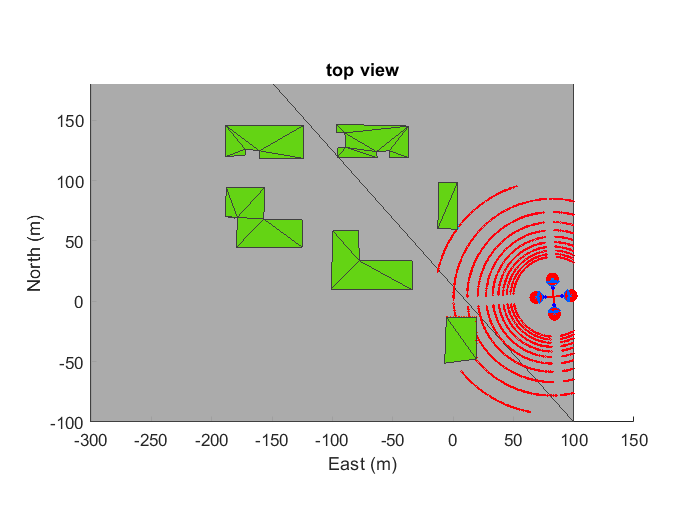


hold off